# ECE 230 Circuit Analysis

## Project 1:  Basic Concepts

**Overview:**  In this project we will document equations and procedures for computing charge, current, voltage, energy and power relationships in addition to Ohm's Law and Conservation of power relationships, series/parallel resistor combinations and$\;\Delta$ to Y conversions

**Tasks:**  For each of the sections below, provide a summary description including pictures, equations and user-interactive code which will be used to solve a variety of test cases provided. 

**Leader: **

**Software Developers:**  

**Testers: ** 

**Documenter/editor:**  

### a) Charge, Current, Voltage, Energy and Power Relationships


$$q\left(t\right)=q_0 +\int i\left(t\right)\cdot \textrm{dt}$$
 


$$i\left(t\right)=\frac{\textrm{dq}\left(t\right)}{\textrm{dt}}$$



$$v\left(t\right)=\frac{\textrm{dw}\left(t\right)}{\textrm{dq}\left(t\right)}$$



$$p\left(t\right)=v\left(t\right)\cdot i\left(t\right)$$



$$w\left(t\right)=w_0 +\int p\left(t\right)\cdot \textrm{dt}$$


%Calculate q(t) given i(t)
syms t
i = 8*t^2

$$i = 8\,t^{2}$$

%indefinite integral
q = int(i,t)

$$q = \frac{8\,t^{3}}{3}$$

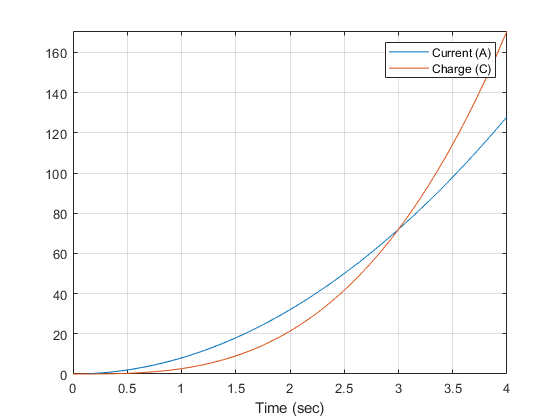

%plot results
figure;fplot([i q],[0 4]);grid on;legend("Current (A)","Charge (C)");xlabel('Time (sec)');

%definite integral calculated between points [a b]
q = int(i,t,[1 2]) 

$$q = \frac{56}{3}$$

%definite integral calculated between points [a b] in decimal form
q = vpaintegral(i,t,[1 2])

$$q = 18.6667$$

%Calculate i(t) given q(t)
syms q(t)
q(t) = 20-15*t-10*exp(-3*t)

$$q(t) = 20-10\,{\mathrm{e}}^{-3\,t}-15\,t$$

%Derivative
i = diff(q,t)

$$i(t) = 30\,{\mathrm{e}}^{-3\,t}-15$$

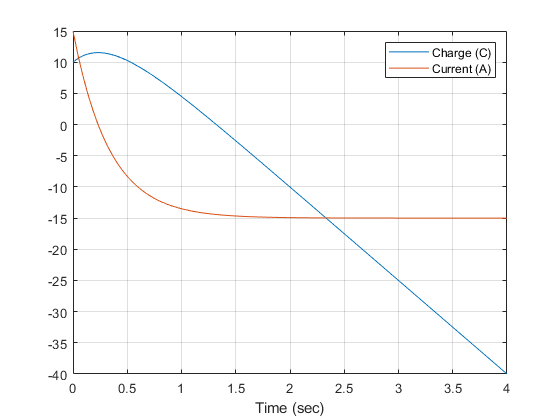

%plot results
figure;fplot([q i],[0 4]);grid on;legend("Charge (C)","Current (A)");xlabel('Time (sec)');


%Derivative evaluated at time
time = 1;
i(time)

$$ans = 30\,{\mathrm{e}}^{-3}-15$$

%evaluate to 5 digits of accuracy
vpa(i(time),5)

$$ans = -13.506$$

%calculate i(t) or q() given piecewise signal
syms t
i = piecewise(0<t<1, 8, t>1, 8*t^2)

$$i = \left\{ \begin{array}{cl} 8 & \text{ if }t\in \left(0,1\right)\\ 8\,t^{2} & \text{ if }1<t \end{array}\right.$$

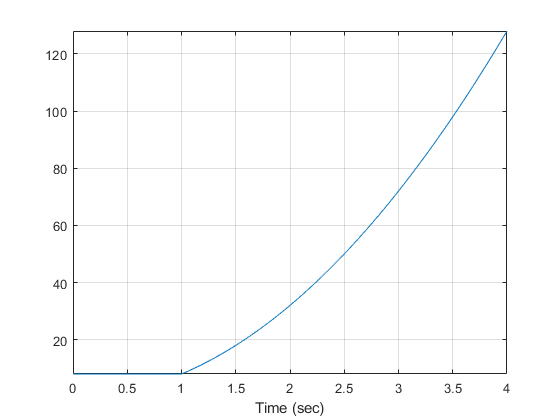

fplot(i,[0 4]);grid on;xlabel('Time (sec)');

q = vpaintegral(i,t,[0 2])

$$q = 26.6667$$


q = piecewise(0<t<=1,10*t,1<t<=2,30-20*t,2<t<=3,-10,3<t<=4,-40+10*t)

$$q = \left\{ \begin{array}{cl} 10\,t & \text{ if }t\in \left(0,1\right]\\ 30-20\,t & \text{ if }t\in \left(1,2\right]\\ -10 & \text{ if }t\in \left(2,3\right]\\ 10\,t-40 & \text{ if }t\in \left(3,4\right] \end{array}\right.$$

i = diff(q,t)

$$i = \left\{ \begin{array}{cl} 10 & \text{ if }t\in \left(0,1\right)\\ -20 & \text{ if }t\in \left(1,2\right)\\ 0 & \text{ if }t\in \left(2,3\right)\\ 10 & \text{ if }t\in \left(3,4\right) \end{array}\right.$$

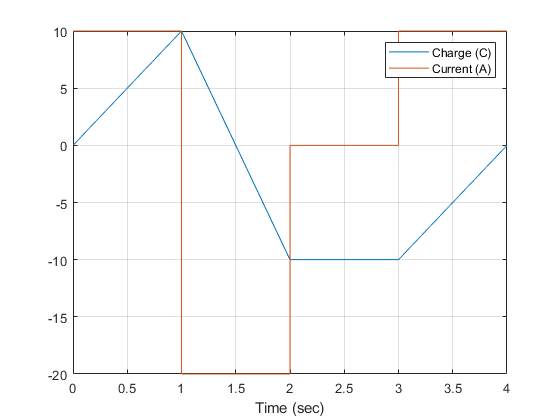

fplot([q i],[0 4]);grid on;legend("Charge (C)","Current (A)");xlabel('Time (sec)');

%Calculate p(t) and w(t) given v(t) and i(t)
syms t i(t) v(t)
i(t) = 5*cos(60*pi*t)

$$i(t) = 5\,\cos\left(60\,\pi \,t\right)$$

v(t) = -900*pi*sin(60*pi*t)

$$v(t) = -900\,\pi \,\sin\left(60\,\pi \,t\right)$$

%v(t) = 3*diff(i(t),t)
p(t) = v(t)*i(t)

$$p(t) = -4500\,\pi \,\cos\left(60\,\pi \,t\right)\,\sin\left(60\,\pi \,t\right)$$

w(t) = int(p(t))

$$w(t) = -\frac{75\,{\sin\left(60\,\pi \,t\right)}^{2}}{2}$$

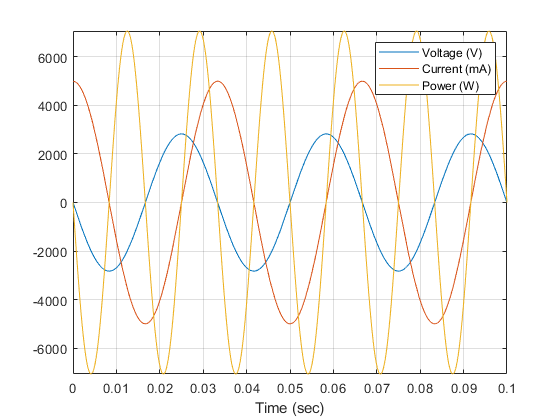

%plot results
figure;fplot([v 1000*i p],[0 0.1]);grid on;legend("Voltage (V)","Current (mA)","Power (W)");xlabel('Time (sec)');

%evaluation at time
time = 3e-3;
vpa(p(time),5)

$$ans = -6395.8$$

w = vpaintegral(p,t,[0 0.01])

$$w = -33.9191$$

Back to TOC

### b) Ohm's Law and Conservation of Power


$$v=\textrm{iR}$$



$$p=v\cdot i=\frac{v^2 }{R}=i^2 \cdot R$$


term = "Current";

if strcmp(term,"Voltage")
    answer = inputdlg('Enter Current in A followed by Resistance in Ohms Separated by Spaces (inf = open and 0 = short):','Voltage Calculation', [1 50]);
    terms = str2num(answer{1});
    v = prod(terms)
    p = v*terms(1)
elseif strcmp(term,"Current")
    answer = inputdlg('Enter Voltage in V followed by Resistance in Ohms Separated by Spaces (inf = open and 0 = short):','Current Calculation', [1 50]);
    terms = str2num(answer{1});
    i = terms(1)/terms(2)
    p = terms(1)*i
else
    answer = inputdlg('Enter Voltage in V followed by Current in Amps Separated by Spaces:','Resistance Calculation', [1 50]);
    terms = str2num(answer{1});
    R = terms(1)/terms(2)
    p = terms(1)*terms(2)
end

i = 41.6667

p = 1.0417e+06

Back to TOC

### c) Series/Parallel Resistor Combinations

Series Resistors:   $R_{\textrm{eq}} =R_1 +R_2 +\cdots +R_N =\sum_{n=1}^N R_n$  

Parallel Resitors:   $\frac{1}{R_{\textrm{eq}} }=\frac{1}{R_1 }+\frac{1}{R_2 }+\cdots +\frac{1}{R_N }$   or  $G_{\textrm{eq}} =G_1 +G_2 +{\cdots +G}_N$     

2 Parallel Resitors:   $R_{\textrm{eq}} =\frac{R_1 \cdot R_2 }{R_1 +R_2 }$

N Parallel resistors all with same value:  $R_{\textrm{eq}} =\frac{R}{N}$

Combo_Type = "Series";

answer = inputdlg('Enter Resistor Values in Ohms Separated by Spaces (inf = open and 0 = short):','Resistor Combinations', [1 50]);
Resistors = str2num(answer{1});
if strcmp(Combo_Type,"Series")
    Req = sum(Resistors)
else
    Req = 1/sum(1./Resistors)
end

Req = 70

Back to TOC

### d) Voltage and Current Dividers

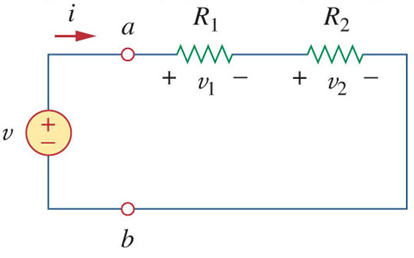

Voltage divider:   $v_1 =\frac{R_1 }{R_1 +R_2 }v$    (2 resistors)   $v_n =\frac{R_n }{R_1 +R_2 +\cdots +R_n }v$   (general case)

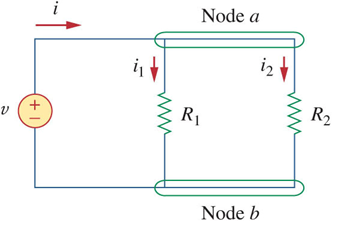

Current divider:   $i_1 =\frac{R_2 }{R_1 +R_2 }i$    (2 resistors)   $i_n =\frac{G_n }{G_1 +G_2 +\cdots +G_n }i$   (general case)

***Use the opposite resistor for current divider!***

clear all;
Combo_Type = "Volt_div";
if strcmp(Combo_Type,"Volt_div")
    answer = inputdlg('Enter Voltage Source in Volts and Resistor Values in Ohms Separated by Spaces (inf = open and 0 = short):','Voltage Divider', [1 50]);
    vals = str2num(answer{1});
    numInf = find(vals==inf);
    if isempty(numInf)
        for i = 2:(length(vals))
            v(i-1) = vals(1)*vals(i)/sum(vals(2:length(vals)));
        end
    else
        v = zeros(1,length(vals)-1);
        v(numInf-1) = vals(1);
        vals(1);
    end
    v
else
    answer = inputdlg('Enter Current Source in Amps and Resistor Values in Ohms Separated by Spaces (inf = open and 0 = short):','Voltage Divider', [1 50]);
    vals = str2num(answer{1});  
    numZeros = find(~vals);
    if isempty(numZeros)
        for k = 2:(length(vals))
            i(k-1) = vals(1)*(1/vals(k))/sum(1./vals(2:length(vals)));
        end
    else
        i = zeros(1,length(vals)-1);
        i(numZeros-1) = vals(1);
    end
    i
end


numInf =

  1×0 empty double row vector



v =      0     4     6


Back to TOC

### e) Delta to Y conversions

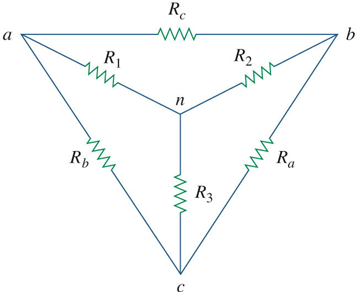

$\;\Delta$*** to Y Conversion***


$$R_1 =\frac{R_b R_c }{R_a +R_b +R_c }$$
    
$$R_2 =\frac{R_a R_c }{R_a +R_b +R_c }$$
    
$$R_3 =\frac{R_a R_b }{R_a +R_b +R_c }$$


$R_Y =\frac{R_{\Delta } }{3}$  (when all resistors are equal)

***Y to ***$\;\Delta$*** Conversion***


$$R_a =\frac{R_1 R_2 +R_2 R_3 +R_1 R_3 }{R_1 }$$
     
$$R_b =\frac{R_1 R_2 +R_2 R_3 +R_1 R_3 }{R_2 }$$
     
$$R_c =\frac{R_1 R_2 +R_2 R_3 +R_1 R_3 }{R_3 }$$
 

$R_{\Delta } =3R_Y$  (when all resistors are equal)

Combo_Type = "Y_to_Delta";

answer = inputdlg('Enter Resistor Values in Ohms Separated by Spaces (inf = open and 0 = short):','Resistor Combinations', [1 50]);
Res = str2num(answer{1});
numInf = find(Res==inf);

%NEED TO ADD CONDITION ON OPEN PHASE
if strcmp(Combo_Type,"Y_to_Delta")

    Ra = (Res(1)*Res(2)+Res(2)*Res(3)+Res(1)*Res(3))/Res(1);
    Rb = (Res(1)*Res(2)+Res(2)*Res(3)+Res(1)*Res(3))/Res(2);
    Rc = (Res(1)*Res(2)+Res(2)*Res(3)+Res(1)*Res(3))/Res(3);    
 
    if numInf == 1
        Ra = Res(2)+Res(3);
    elseif numInf == 2
        Rb = Res(1)+Res(3);
    elseif numInf == 3
        Rc = Res(1)+Res(2);            
    end
    
    Ra
    Rb
    Rc
else
    R1 = (Res(2)*Res(3))/sum(Res);
    R2 = (Res(1)*Res(3))/sum(Res);
    R3 = (Res(1)*Res(2))/sum(Res);
    
    if numInf == 1
        R1 = 0;
        R2 = Res(3);
        R3 = Res(2);
    elseif numInf == 2
        R1 = Res(3);
        R2 = 0;
        R3 = Res(1);
    elseif numInf == 3
        R1 = Res(2);
        R2 = Res(1);
        R3 = 0;          
    end
    
    R1
    R2
    R3
end

Ra = 30

Rb = Inf

Rc = 40

Back to TOC

## Project 2:  Circuit Analysis Techniques

**Overview:**  In this project we will document equations and procedures for use in Nodal Analysis, Mesh Analyis and Superposition circuit techniques

**Tasks:**  For each of the sections below, provide a summary description including pictures, equations and user-interactive code which will be used to solve a variety of test cases provided. 

**Leader: **

**Software Developers:**  

**Testers: ** 

**Documenter/editor:**  

### a) Nodal Analysis

Given a circuit with **N** nodes and** M** voltage sources the process for nodal analysis is:

- Select reference node (0V)

- Label remaining **N-1** nodes

- Assume current and voltage polarities using passive sign convention

- Create a supernode for each voltage source

- Write **N-1-M** KCL equations

- For each resistive branch express current in terms of node voltage and resistance using Ohm's Law

- Write KVL equations for the **M** voltage sources

- Solve the **N-1** simulataneous equations

Back to TOC

### b) Matrix Math in MATLAB

GIven a system of equations


$$\begin{array}{l}
2x_1 +3x_2 =4\\
5x_1 +6x_2 =7
\end{array}$$


Write in maxtrix form AX=B and solve for X


$$X=A^{-1} B$$


A = [2 3;5 6] 

A =      2     3
     5     6


B = [4;7]

B =      4
     7


X = inv(A)*B

X =          0
   24.0000


Back to TOC

### c) Mesh Analysis

Given a circuit with **N** meshes the process for mesh analysis is:

- Assign mesh currents to all meshes

- Assume resistor voltage drop polarities based on passive sign convention

- For any current sources  

-     If just one mesh, assign mesh current to the current source and do not write KVL around that mesh

-     If between meshes create a supermesh

- Write KVL for each mesh including supermeshes

- Write resistor voltages in terms of mesh currents and resistance using Ohm's Law

- Use KCL to relate mesh currents at each current source

- Solve the resulting simultaneous equations

Back to TOC

### d) Superposition

General process for superpoisition is:

- Consider one independent source at a time (turn off all others)

- Sources are turned off by (shorting voltage sources, opening current sources)

- Dependent sources always remain

- Find response due to that independent source

- Repeat for all independent sources

- Algebraically sum the responses for the total response

Back to TOC

## Project 3:  Circuit Transformation Techniques

**Overview:**  In this project we will document equations and procedures for computing source transformations, Thevenin equivalent circuits, Norton equivalent circuits and to identify the conditions for and how to calculate maximum power transfer in a circuit.  

**Tasks:**  For each of the sections below, provide a summary description including pictures, equations and user-interactive code which will be used to solve a variety of test cases provided. 

**Leader: **

**Software Developers:**  

**Testers: ** 

**Documenter/editor:**  

### a) Source Transformations

Back to TOC

### b) Thevenin Equivalent Circuits

Back to TOC

### c) Norton Equivalent Circuits

Back to TOC

### d) Maximum Power Transfer

Back to TOC

## Project 4:  Op-Amps and Other Passive Components

**Overview:**  In this project we will document equations and procedures for computing commonly found op-amp configurations, series/parallel inductor/capacitor combinations, voltage/current relationships for inductors/capacitors and energy calculations for inductors/capacitors 

**Tasks:**  For each of the sections below, provide a summary description including pictures, equations and user-interactive code which will be used to solve a variety of test cases provided. 

**Leader: **

**Software Developers:**  

**Testers: ** 

**Documenter/editor:**  

### a) Op-Amp Circuit Configurations

Back to TOC

### b) Series/Parallel Inductor/Capacitor Combinations

Back to TOC

### c) Voltage/Current Relationships for Inductors/Capacitors

Back to TOC

### d) Energy Calculations for Inductors/Capacitors

Back to TOC

## Project 5:  Differential Equation Circuit Techniques and Singularity Functions

**Overview:**  In this project we will document equations and procedures for computing first and second order differential equations including initial conditions for use in electric circuit analysis and for computing equations for singularity functions

**Tasks:**  For each of the sections below, provide a summary description including pictures, equations and user-interactive code which will be used to solve a variety of test cases provided. 

**Leader: **

**Software Developers:**  

**Testers: ** 

**Documenter/editor:**  

### a) First-Order Circuits

Back to TOC

### b) Second-Order Circuits

Back to TOC

### c) Singularity Functions

Back to TOC

## Project 6:  Impedance Combinations, Phasors and Single-Phase AC Power

**Overview:**  In this project we will document equations and procedures for computing series/parallel impedance combinations, calculating/graphing phasors from time domain expressions, computing single-phase AC power and drawing power triangles and computing power factor correction calculations

**Tasks:**  For each of the sections below, provide a summary description including pictures, equations and user-interactive code which will be used to solve a variety of test cases provided. 

**Leader: **

**Software Developers:**  

**Testers: ** 

**Documenter/editor:**  

### a) Series/Parallel Impedance Combinations

Back to TOC

### b) Phasors

Back to TOC

### c) Single-Phase AC Power Calculations

Back to TOC

### d) Power Factor Correction

Back to TOC

## Project 7: Transformers and Filters

**Overview:**  In this project we will document equations and procedures for computing relationships for linear and ideal transformers and for identifying and solving passive/active first-order filters as well as computing magnitude/phase frequency plots of first and second order transfer functions

**Tasks:**  For each of the sections below, provide a summary description including pictures, equations and user-interactive code which will be used to solve a variety of test cases provided. 

**Leader: **

**Software Developers:**  

**Testers: ** 

**Documenter/editor:**  

### a) Linear Transformers

Back to TOC

### b) Ideal Transformers

Back to TOC

### c) First-Order Filters

Back to TOC

### d) Transfer Functions

Back to TOC